**MATLAB Book: Chapter 3**

**Section 3.2**


A=[1 2;3 4];
B=[3 4;1 2];
S=A+B

S =      4     6
     4     6


%% if statement
x=randi(20,1);
disp(['The value of x:', num2str(x)])

The value of x:20


x=randi(20,1);
disp(['The value of x:', num2str(x)])

The value of x:20


%% if statement
if (x>10)
    disp('x is greater than 10')
end

x is greater than 10


x=randi(100,1);
disp(['The value of x:', num2str(x)])

The value of x:16


%fprintf('The value of x: %d',x)
if (x>=80)
    disp('Grade: A')
elseif (x>=60 && x<80)
    disp('Grade: B')
elseif (x>=40 && x<60)
    disp('Grade: C')
else
    disp('Grade: F')
end

Grade: F


x=input('Enter a Month:','s');
switch x
    case 'January'
        disp(['Number of Days in ',x,':31'])
    case 'February'
        disp(['Number of Days in ',x,':28'])
    case 'March'
        disp(['Number of Days in ',x,':31'])
    case 'April'
        disp(['Number of Days in ',x,':30'])
    case 'May'
        disp(['Number of Days in ',x,':31'])
    case 'June'
        disp(['Number of Days in ',x,':30'])
    case 'July'
        disp(['Number of Days in ',x,':31'])
    case 'August'
        disp(['Number of Days in ',x,':31'])
    case 'September'
        disp(['Number of Days in ',x,':30'])
    case 'October'
        disp(['Number of Days in ',x,':31'])
    case 'November'
        disp(['Number of Days in ',x,':30'])
    case 'December'
        disp(['Number of Days in ',x,':31'])
    otherwise
        disp('Enter a Correct Name of Month')
end

Number of Days in July:31


[out1, out2]=myfunction(10,20)

out1 = 20

out2 = 40

myfunc = @(x) 2*x+3

myfunc = function_handle with value:
    @(x)2*x+3


myfunc = @(x) 2*x+3

myfunc = function_handle with value:
    @(x)2*x+3


myfunc(2)

ans = 7

% Real Power,R = 10 W
% Reactive Power,Q = 20 VAR
% Aparent power,S is a complex number.

R=10; Q=20;
% Rectangular form
S_rec=complex(10,20);
disp('Apparent power in rectangular form:');

Apparent power in rectangular form:


S_rec

S_rec = 10.0000 + 20.0000i

% Polar form
S_mag=abs(S_rec);
S_angle=angle(S_rec)*(180/pi); % Unit: Degree
S_polar=[S_mag,S_angle];
disp('Apparent power in polar form- [Magnitude  Angle(Degree)]:');

Apparent power in polar form- [Magnitude  Angle(Degree)]:


S_polar

S_polar =    22.3607   63.4349


% Resistance, R=5 ohms
% Capacitance, C=2 micro F
% Inductance, L=15 mH
% Frequency, f=60Hz
% Impedance, Z=R+jX=R+j(X_L-X_C)
% Here, 
% X_L=Inductive Reactance=omega*L=2*pi*f*L
% X_C=Capactive Reactance=1/(omega*C)=-1/(2*pi*f*C)

R=5; L=15*10^(-3); C=2*10^(-6); f=60; 
X_L=2*pi*f*L;
X_C=-1/(2*pi*f*C);
% Rectangular form
Z_rec=R+i*(X_L-X_C);
disp('Impedance in rectangular form:');

Impedance in rectangular form:


Z_rec

Z_rec = 5.0000e+00 + 1.3319e+03i

% Polar form
Z_mag=abs(Z_rec);
Z_angle=angle(Z_rec)*(180/pi); % Unit: Degree
Z_polar=[Z_mag,Z_angle];
disp('Impedance in polar form- [Magnitude  Angle(Degree)]:');

Impedance in polar form- [Magnitude  Angle(Degree)]:


Z_polar

Z_polar = 	1.0e+03 *

    1.3320    0.0898


% Real value, a=2
% Imaginary value, b=5
% Complex number, C=a+i*b
a=2; b=5;
C=a+i*b

C = 2.0000 + 5.0000i

% Real value, a=2
% Imaginary value, b=5
% Complex number, C=a+i*b
a=2; b=5;
C=complex(a,b)

C = 2.0000 + 5.0000i

% Complex number, C=a+i*b = 2+5i
a=2; b=5;
C_mag=sqrt(a^2+b^2);
C_angle=atan(b/a)*(180/pi); % in degree
C_polar=[C_mag,C_angle]

C_polar =     5.3852   68.1986


% Complex number, C=a+i*b = 2+5i
a=2; b=5;
C=complex(a,b);
C_mag=abs(C);
C_angle=angle(C)*(180/pi); % in degree
C_polar=[C_mag,C_angle]

C_polar =     5.3852   68.1986


% Complex number, C=a+i*b = 2+5i
a=2; b=5;
C=complex(a,b);
[C_angle, C_mag]=cart2pol(a,b);
C_angle=C_angle*(180/pi); %in degree
C_polar=[C_mag,C_angle]

C_polar =     5.3852   68.1986


% C1= 2+5i
% C2= 5+10i
% Convert C1 and C2 in exponential form
% Determine M=C1*C2 and D=C1/C2 in exponential form

C1=complex(2,5);
C2=complex(5,10);
C1_mag=abs(C1);
C1_angle=angle(C1);
C2_mag=abs(C2);
C2_angle=angle(C2);
% C=a+bi=|C|(cos(theta)+i*sin(theta))=|C|exp(i*theta)
disp(['C1 in exponential form: ', num2str(C1_mag),'exp(i*',...
                                     num2str(C1_angle),')']);

C1 in exponential form: 5.3852exp(i*1.1903)


disp(['C2 in exponential form: ', num2str(C2_mag),'exp(i*',...
                                     num2str(C2_angle),')']);

C2 in exponential form: 11.1803exp(i*1.1071)


% C1*C2
M_mag=C1_mag*C2_mag;
M_angle=C1_angle+C2_angle;
disp(['C1*C2 in exponential form: ', num2str(M_mag),'exp(i*',...
                                     num2str(M_angle),')']);

C1*C2 in exponential form: 60.208exp(i*2.2974)


% C1/C2
D_mag=C1_mag/C2_mag;
D_angle=C1_angle-C2_angle;
disp(['C1/C2 in exponential form: ', num2str(D_mag),'exp(i*',...
                                     num2str(D_angle),')']);

C1/C2 in exponential form: 0.48166exp(i*0.083141)


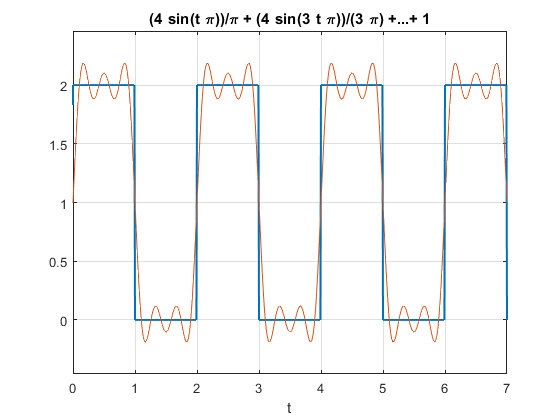

% Input: Square wave function
% T=2; Magnitude = 1; Omega=pi
t=-7:0.01:7;
x=1-square(pi*(t+1));
plot(t,x,'LineWidth',1.5)
grid on;
hold on;

% Fourier Series
syms k t
omega=pi;
T=2;
k=1:5;
a_0=(2/T)*int(2,t,0,1);
a_k=(2/T)*int(2*cos(k*omega*t),t,0,1);
b_k=(2/T)*int(2*sin(k*omega*t),t,0,1);
f=(a_0/2)+sum(a_k.*cos(k*omega*t))+sum(b_k.*sin(k*omega*t));
ezplot(f,[0,7])  
grid on;

% disp function
clear;clc;
var = 5.25;
disp('Usage of disp() function:');
disp(var);
disp(['The value of the variable is: ',num2str(var)]);